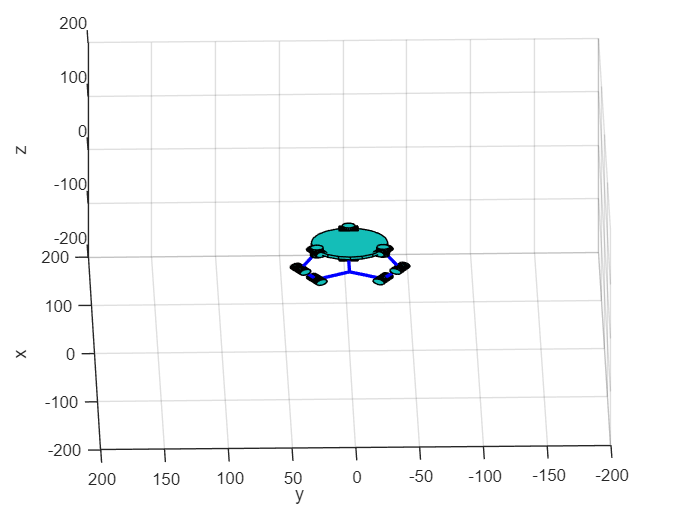

clear all;cla;
global Link_1
global Link_2
global Link_3
Build;
% load('Link_1.mat','Link_1');
% load('Link_2.mat','Link_2');
% load('Link_3.mat','Link_3');
% ROM;
view(134,12);
% stp=5;
% for i=0:stp:60
%    DHFk_hand([0,i,20,i+20],[-i,i,20,i+20],[i,i,20,i+20],true)
%    drawnow;hold off;
% end

q=repmat(0,1,4);
q1=[0,60,60,60];%0,0,-51.9615
DHFk_hand(q1,q1,q1,true)


% 定义球的半径和中心位置
ball_radius = 20;
ball_center = [0, 0, -50];

% 确定接触点位置
theta1 = 0; % 接触点1的角度
phi1 = pi/2;  % 接触点1的角度
contact_point1 = ball_center + ball_radius * [cos(theta1) * sin(phi1), sin(theta1) * sin(phi1), cos(phi1)];

theta2 = 2*pi/3; % 接触点2的角度
phi2 = pi/2;  % 接触点2的角度
contact_point2 = ball_center + ball_radius * [cos(theta2) * sin(phi2), sin(theta2) * sin(phi2), cos(phi2)];

theta3 = -2*pi/3; % 接触点3的角度
phi3 = pi/2;  % 接触点3的角度
contact_point3 = ball_center + ball_radius * [cos(theta3) * sin(phi3), sin(theta3) * sin(phi3), cos(phi3)];
% 绘制球和接触点
figure;
DrawSphere(ball_center,ball_radius,0);
hold on;
plot3(contact_point1(1), contact_point1(2), contact_point1(3), 'ro', 'MarkerSize', 10, 'LineWidth', 2);
plot3(contact_point2(1), contact_point2(2), contact_point2(3), 'go', 'MarkerSize', 10, 'LineWidth', 2);
plot3(contact_point3(1), contact_point3(2), contact_point3(3), 'bo', 'MarkerSize', 10, 'LineWidth', 2);

xlabel('X');
ylabel('Y');
zlabel('Z');
title('球的接触点');
grid on;
hold off;
axis equal;

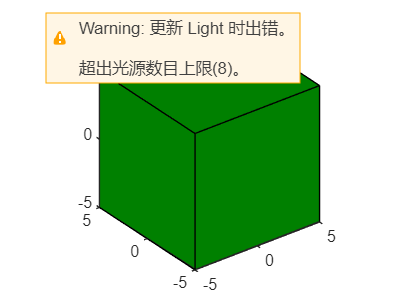

clear all;cla;
% axis([-200,200,-200,200,-200,200]);
% 定义正方体的中心位置、边长和颜色
cube_center = [0, 0, 0];
cube_side = 10;
cube_color = [0, 0.5, 0]; % 绿色
DrawCube(cube_center, cube_side,cube_color);

% clear all;cla;
load('FK_matrix.mat', 'FK_matrix');

disp(FK_matrix)

函数或变量 'FK_matrix' 无法识别。

global FK;
FK = matlabFunction(FK_matrix);
end_effector_pos= FK(0,0,0,0,0);
end_effector_pos=end_effector_pos(1:3,4)';